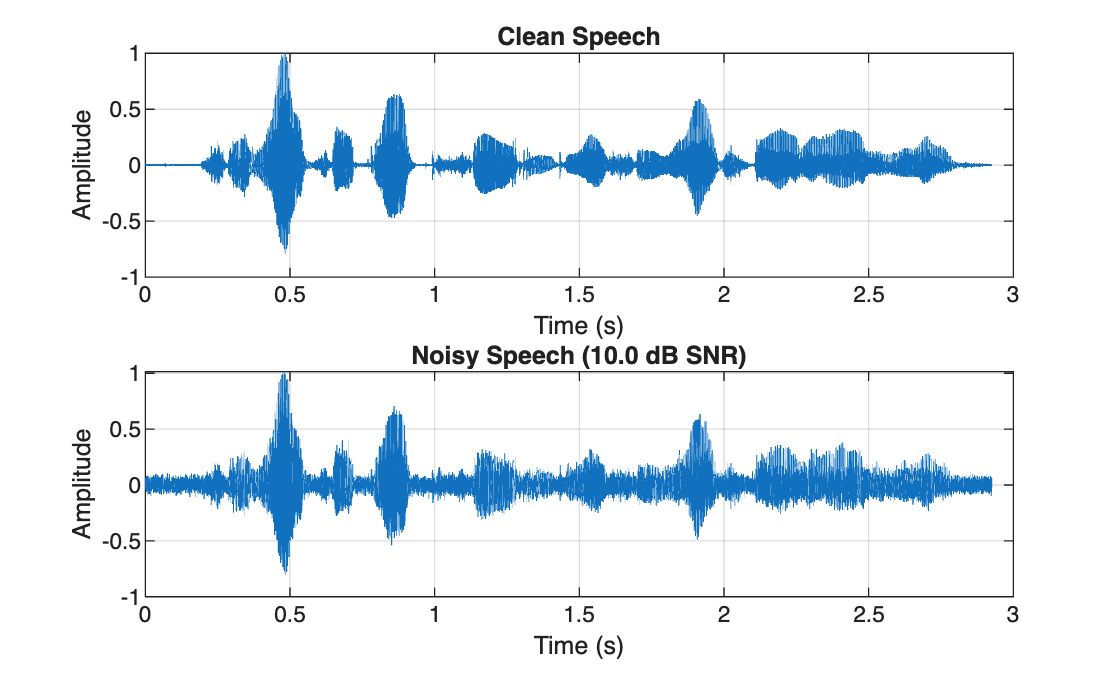

%% ELEC5305 Project: Speech Enhancement using Spectral Subtraction and STFT
% Author: Joshua Chao-Hsu Chen
% SID: 510656681
clc; clear; close all

%% Load clean speech

[clean, fs] = audioread('LDC93S1.wav');
if size(clean,2) > 1
    clean = mean(clean,2); % convert to mono if stereo
end

% Normalize amplitude
clean = clean ./ max(abs(clean));

% sound(clean, fs)

%% Add noise (AWGN or recorded environmental)
snr_input = 10; % desired input SNR in dB
noisy = awgn(clean, snr_input, 'measured');

figure;
subplot(2,1,1);
plot((0:length(clean)-1)/fs, clean); grid on
xlabel('Time (s)'); ylabel('Amplitude');
title('Clean Speech');

subplot(2,1,2);
plot((0:length(noisy)-1)/fs, noisy); grid on
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('Noisy Speech (%.1f dB SNR)', snr_input));

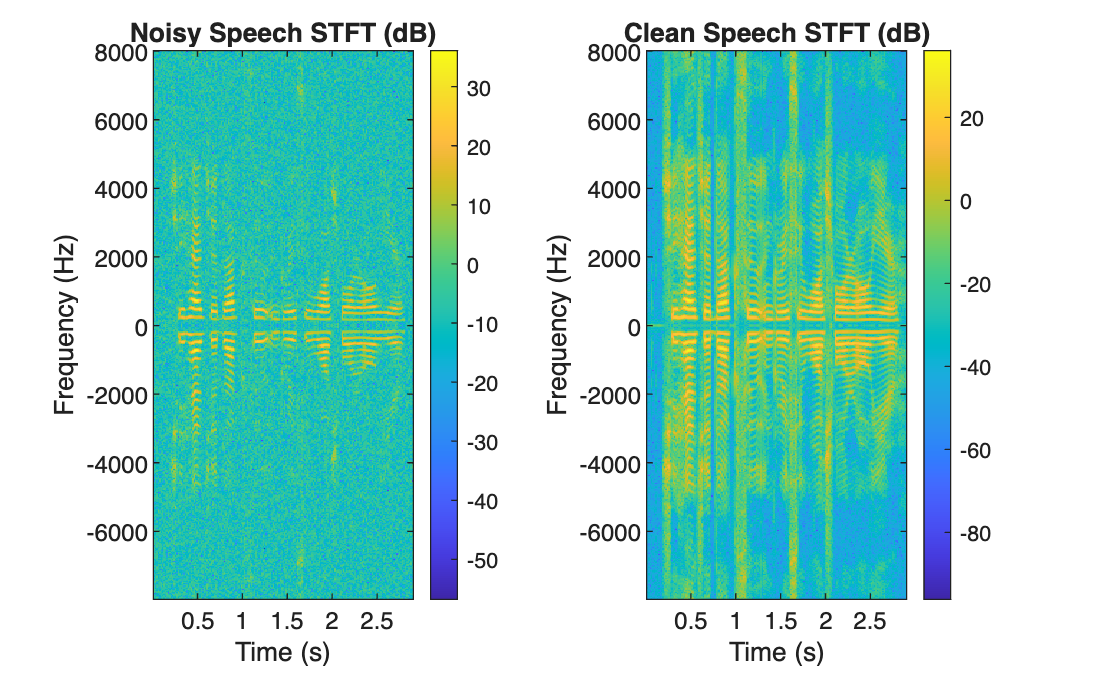


%% Parameters for STFT
win_len = 512;
hop = win_len/2;
window = hann(win_len, 'periodic');
nfft = 512;

%% STFT analysis
[S_noisy, f, t] = stft(noisy, fs, 'Window', window, 'OverlapLength', hop, 'FFTLength', nfft);
S_clean = stft(clean, fs, 'Window', window, 'OverlapLength', hop, 'FFTLength', nfft);

figure;
subplot(1,2,1);
imagesc(t, f, mag2db(abs(S_noisy))); axis xy;
xlabel('Time (s)'); ylabel('Frequency (Hz)');
title('Noisy Speech STFT (dB)');
colorbar;

subplot(1,2,2);
imagesc(t, f, mag2db(abs(S_clean))); axis xy;
xlabel('Time (s)'); ylabel('Frequency (Hz)');
title('Clean Speech STFT (dB)');
colorbar;


%% Estimate noise spectrum (simple approach)
% Average first 0.5 s assuming silence or low speech activity
noise_frames = find(t <= 0.5);
N_hat = mean(abs(S_noisy(:, noise_frames)), 2);

%% Spectral Subtraction
S_mag = abs(S_noisy);
S_phase = angle(S_noisy);

% Oversubtraction factor
alpha = 1.0;  

% Apply subtraction
S_mag_enh = max(S_mag - alpha * N_hat, 0);

% Reconstruct with original phase
S_enh = S_mag_enh .* exp(1j * S_phase);

%% Inverse STFT (iSTFT)
enh = istft(S_enh, fs, 'Window', window, 'OverlapLength', hop, 'FFTLength', nfft);

% Match length to original
enh = enh(1:min(length(enh), length(clean)));

%% Evaluate SNR improvement
clean = clean(:);
noisy = noisy(:);
enh   = enh(:);

L = min([numel(clean) numel(noisy) numel(enh)]);
clean = clean(1:L);
noisy = noisy(1:L);
enh   = enh(1:L);

snr_in  = snr(clean, noisy - clean);
snr_out = snr(clean, enh   - clean);
fprintf('Input SNR: %.2f dB | Enhanced SNR: %.2f dB\n', snr_in, snr_out);

Input SNR: 10.02 dB | Enhanced SNR: -9.98 dB


fprintf('\nInput SNR: %.2f dB\nEnhanced SNR: %.2f dB\n', snr_in, snr_out);


Input SNR: 10.02 dB
Enhanced SNR: -9.98 dB



%% Plot and compare waveforms
t_axis = (0:length(clean)-1)/fs;

figure;
subplot(3,1,1); plot(t_axis, clean); grid on;
title('Clean Speech'); ylabel('Amplitude');

subplot(3,1,2); plot(t_axis, noisy); grid on;
title('Noisy Speech'); ylabel('Amplitude');

subplot(3,1,3); plot(t_axis, enh); grid on;

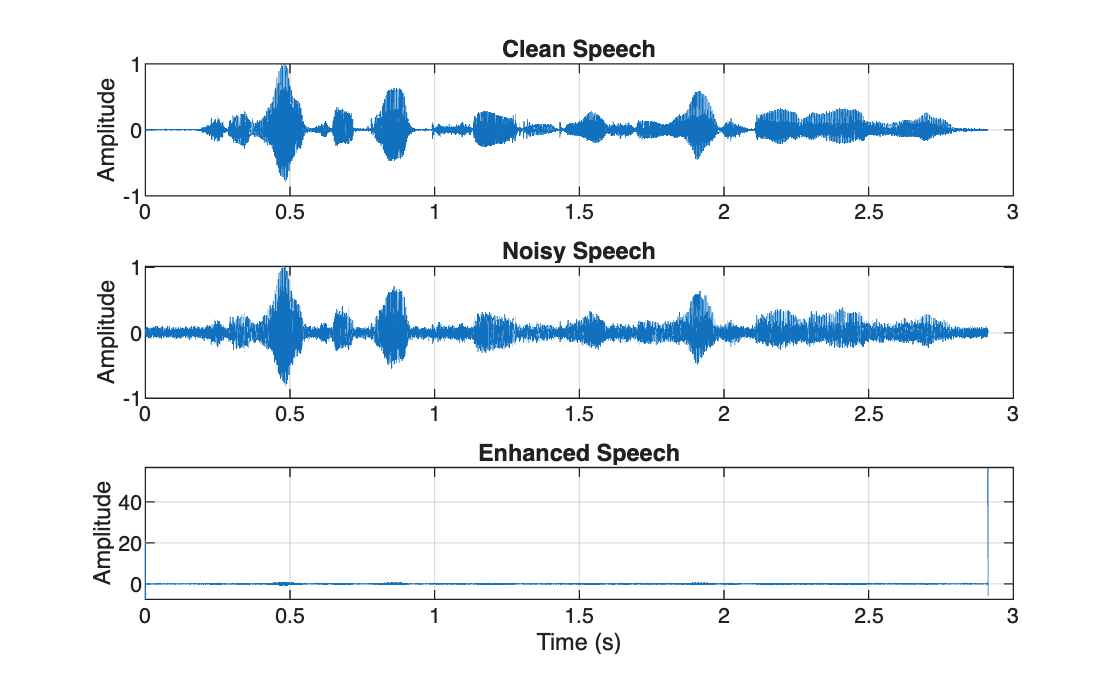

title('Enhanced Speech'); ylabel('Amplitude'); xlabel('Time (s)');

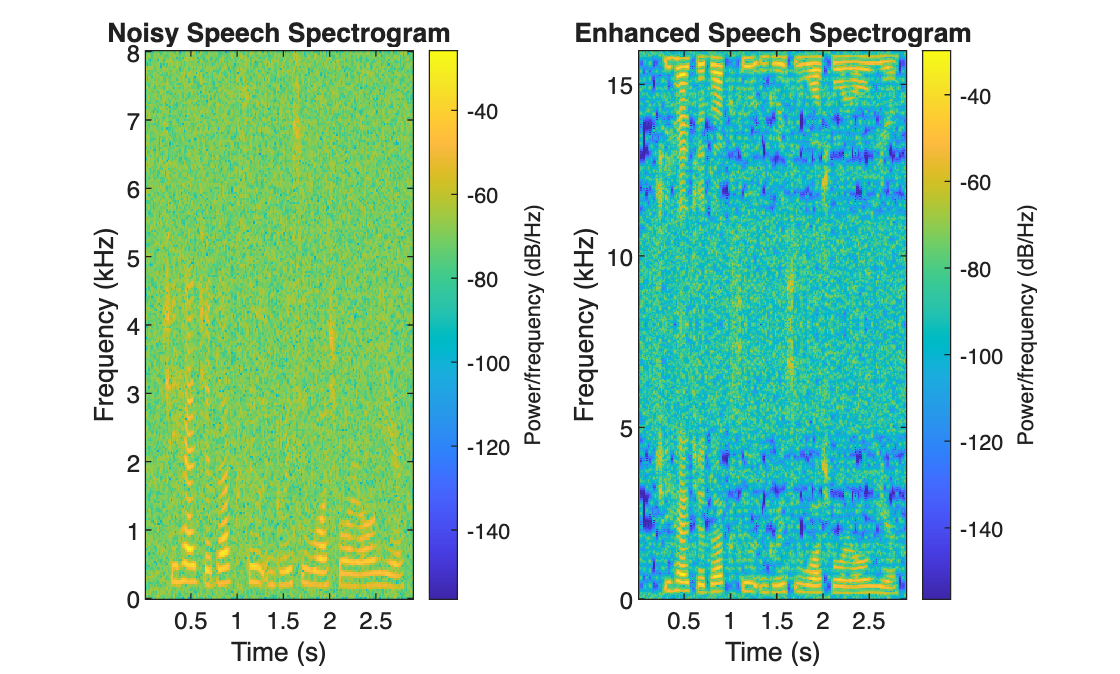


%% Plot spectrograms (before vs after enhancement)
figure;
subplot(1,2,1);
spectrogram(noisy, window, hop, nfft, fs, 'yaxis');
title('Noisy Speech Spectrogram');

subplot(1,2,2);
spectrogram(enh, window, hop, nfft, fs, 'yaxis');
title('Enhanced Speech Spectrogram');


% sound(enh, fs)
enh = real(enh);
audiowrite('enhanced_speech.wav', enh, fs);